# **TU: Decision Tree**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

**Gyeonheal An**

**21900416**

## Introduction

Classification with decision tree

## Example

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

clear

%% Train
addpath("../../Dataset/CWRU_selected_Dataset/Feature_data/");
load("sample_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);

%% Test
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);

#### Plot Test Data

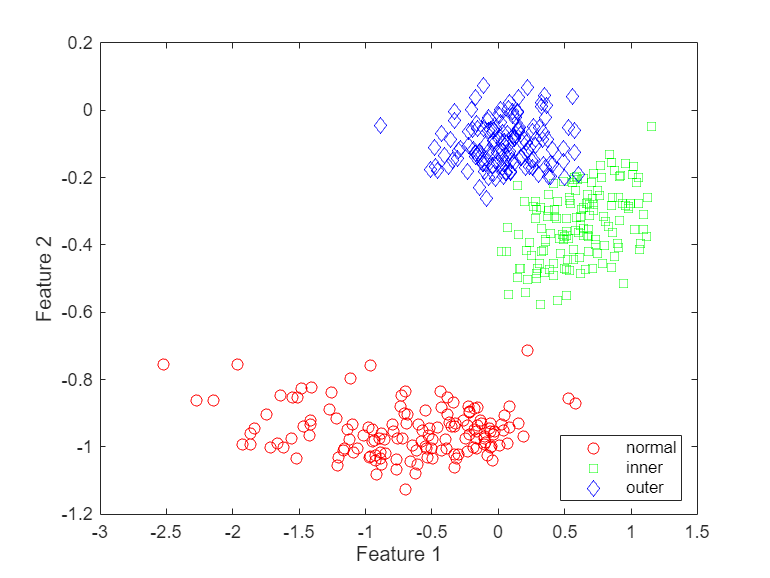

f = figure;
gscatter(X(:, 1), X(:, 2), Y,'rgb','osd');
xlabel('Feature 1')
ylabel('Feature 2')

### Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43
          IsCustom: 0

### Fit decision Tree

t = fitctree(X, Y,'PredictorNames',{'SV' 'IF' });

### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

tResubErr = resubLoss(t)

tResubErr = 0.0023

**Confusion matrix** on the training set

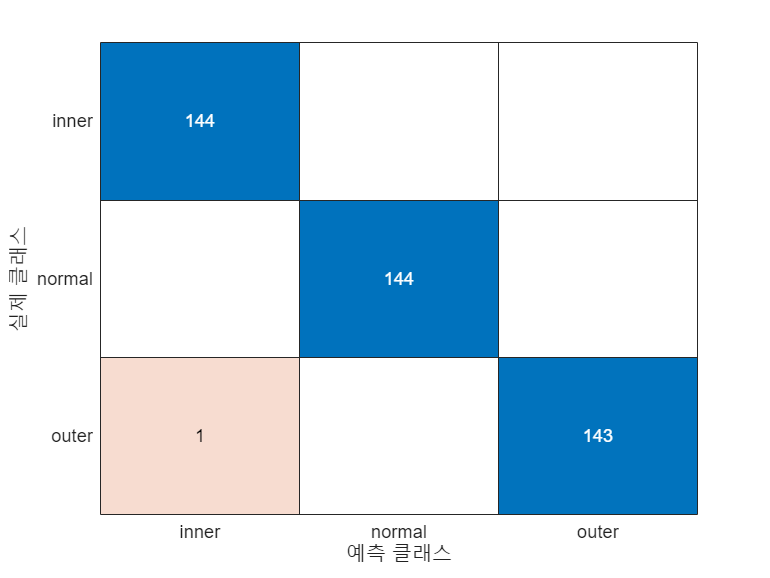

tClass = resubPredict(t);
figure
tResubCM = confusionchart(Y,tClass);

**Misclassification Plot**

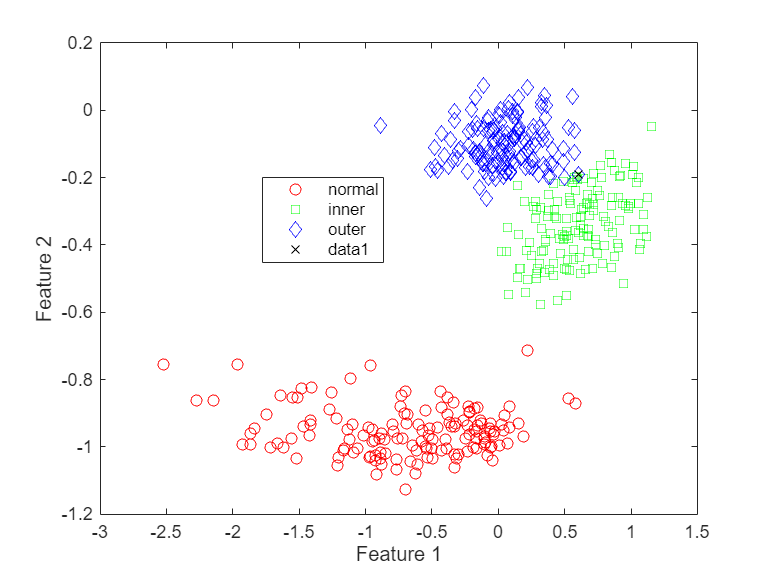

figure(f)
bad = ~strcmp(tClass,Y);
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;

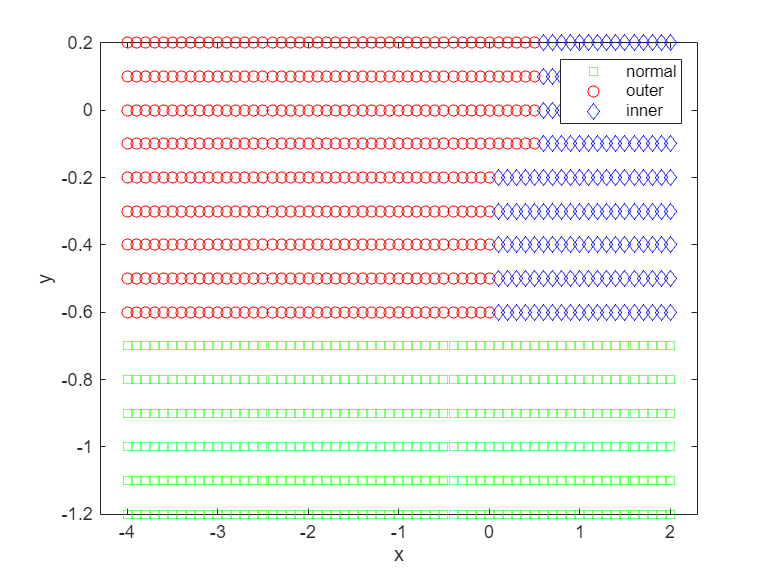

% Visualize Separation regions 
[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
[grpname,node] = predict(t,[x y]);
gscatter(x,y,grpname,'grb','sod')

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

cvt = crossval(t,'CVPartition',cv);
tCVErr = kfoldLoss(cvt)

tCVErr = 0.0069

**visualize the decision tree **

view(t,'Mode','graph');


**Prune tree nodes to enhance result**

- First compute the resubstitution error for various subsets of the original tree. 

- Then compute the cross-validation error for these sub-trees. 

resubcost = resubLoss(t,'Subtrees','all')

resubcost =     0.0023
    0.0093
    0.0347
    0.3333
    0.6667


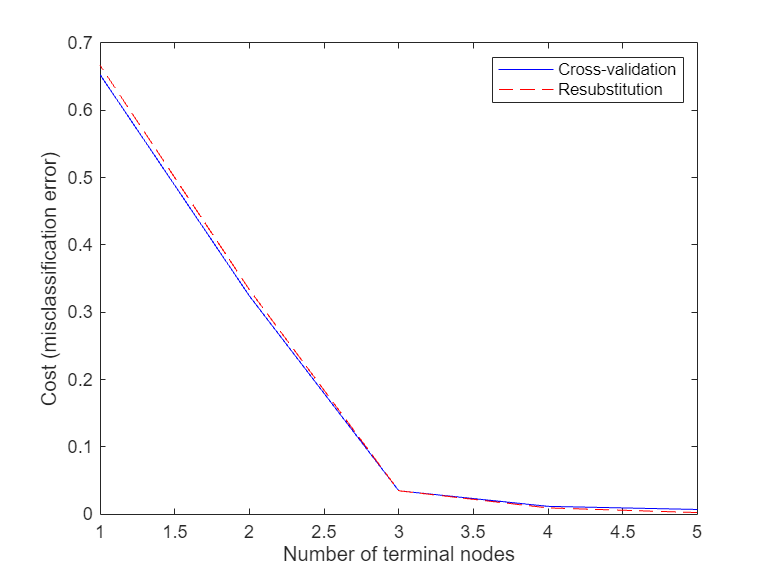

[cost,secost,ntermnodes,bestlevel] = cvloss(t,'Subtrees','all');

plot(ntermnodes,cost,'b-', ntermnodes,resubcost,'r--')
xlabel('Number of terminal nodes');
ylabel('Cost (misclassification error)')
legend('Cross-validation','Resubstitution')


% Prune Tree Levels
pt = prune(t,'Level',bestlevel);
cost(bestlevel+1)

ans = 0.0069

view(pt,'Mode','graph')



# Exercise

## Exercise 1: 

Now, Select any 3 features and repeat the process. 

**Features**

% Example
X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Plot the test and train results in 3D graph.

f = figure;

tableX = glob_all_train(:,{'kv','mf','cf'});

scatter3(tableX,'kv','mf','cf','ColorVariable','kv');
xlabel('Feature 1: Kurtosis Value');
ylabel('Feature 2: Marginal-Factor');
zlabel('Feature 3: Marginal-Factor');
rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43
          IsCustom: 0


t = fitctree(X, Y,'PredictorNames',{'KV' 'MF', 'CF' });
tResubErr = resubLoss(t)

tResubErr = 0

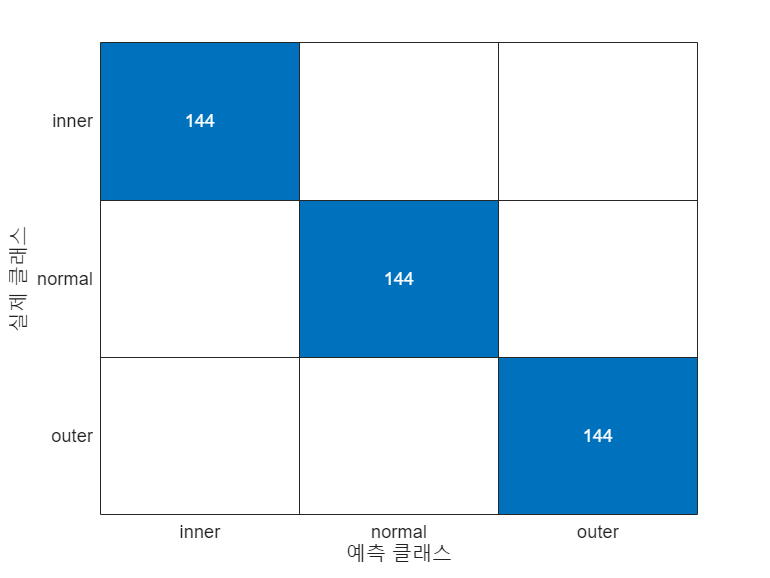


tClass = resubPredict(t);
figure
tResubCM = confusionchart(Y,tClass);

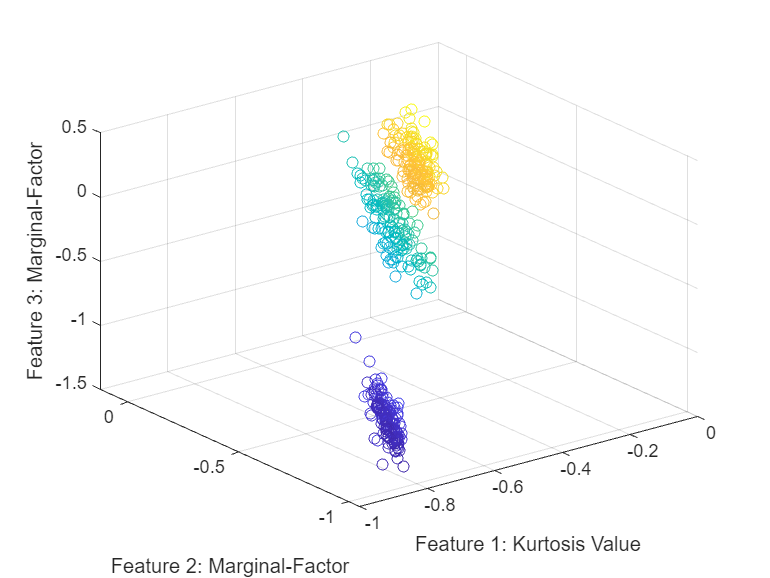


figure(f)
bad = ~strcmp(tClass,Y);


hold on;
%plot(Xtrain(bad,1), Xtrain(bad,2), 'kx');
hold off;

cvt = crossval(t,'CVPartition',cv);
tCVErr = kfoldLoss(cvt)

tCVErr = 0

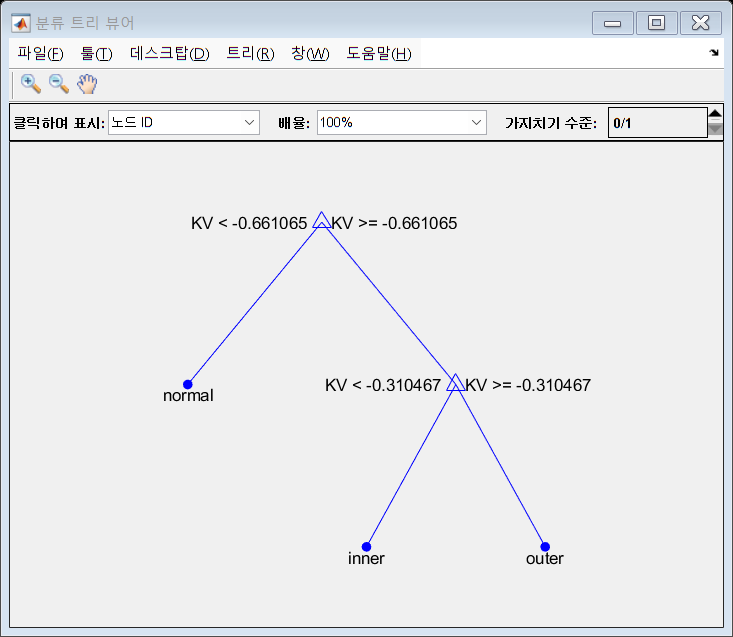


view(t,'Mode','graph');

resubcost = resubLoss(t,'Subtrees','all')

resubcost =          0
    0.6667


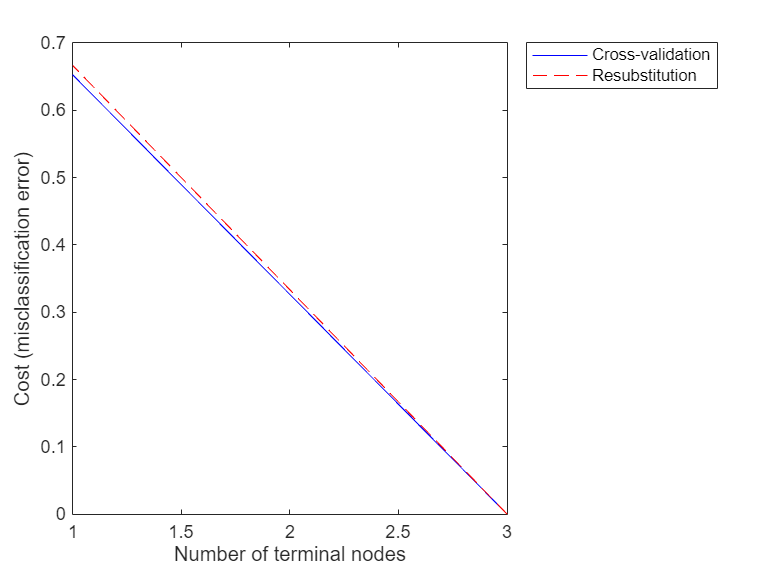


[cost,secost,ntermnodes,bestlevel] = cvloss(t,'Subtrees','all');

plot(ntermnodes,cost,'b-', ntermnodes,resubcost,'r--')
xlabel('Number of terminal nodes');
ylabel('Cost (misclassification error)')
legend('Cross-validation','Resubstitution')


% Prune Tree Levels
pt = prune(t,'Level',bestlevel);
cost(bestlevel+1)

ans = 0

view(pt,'Mode','graph')

Compare performance with other classification 

Look for a random forest model in Matlab